# Modelagem SIR a partir de dados em csv

Nome: Arthur Wypych / Ra: 19.00565-2

## Boas práticas

clc;
clear all;
close all;

## Lendo csv

M = readmatrix('SIRpd')

M =   499.0000    1.0000         0
  498.9490    1.0407    0.0102
  498.8960    1.0831    0.0208
  498.8408    1.1273    0.0319
  498.7834    1.1732    0.0434
  498.7236    1.2210    0.0554
  498.6615    1.2707    0.0679
  498.5968    1.3224    0.0808
  498.5294    1.3762    0.0943
  498.4594    1.4322    0.1084



Sd = M(:,1)

Sd =   499.0000
  498.9490
  498.8960
  498.8408
  498.7834
  498.7236
  498.6615
  498.5968
  498.5294
  498.4594


Id = M(:,2)

Id =     1.0000
    1.0407
    1.0831
    1.1273
    1.1732
    1.2210
    1.2707
    1.3224
    1.3762
    1.4322


Rd = M(:,3)

Rd =          0
    0.0102
    0.0208
    0.0319
    0.0434
    0.0554
    0.0679
    0.0808
    0.0943
    0.1084


## Criando um ruido (dificulta a modelagem)

a = 0;
b = mean(Sd)/10;
c = mean(Id)/5;
d = mean(Rd)/10;
Sdn = (b-a).*rand(length(Sd),1) + a

Sdn =     2.8654
    3.5685
    4.8653
    7.8094
    5.9128
    6.1083
    5.4230
    0.0713
    4.4463
    1.2246


Idn = (c-a).*rand(length(Id),1) + a

Idn =     1.3987
    5.0177
    3.4924
    5.7019
    7.2502
    4.4948
    9.7151
    7.6954
    2.0325
    3.1422


Rdn = (d-a).*rand(length(Rd),1) + a

Rdn =    34.6500
    6.0212
   36.7870
    3.7167
   30.3968
   25.3028
   35.3713
   17.8821
   29.0557
   27.8406


%somando o ruido ao sinal original
Sdnew = Sd + Sdn

Sdnew =   501.8654
  502.5175
  503.7613
  506.6502
  504.6962
  504.8320
  504.0845
  498.6681
  502.9757
  499.6840


Idnew = Id + Idn

Idnew =     2.3987
    6.0584
    4.5756
    6.8292
    8.4234
    5.7157
   10.9857
    9.0178
    3.4087
    4.5744


Rdnew = Rd + Rdn

Rdnew =    34.6500
    6.0314
   36.8078
    3.7486
   30.4402
   25.3582
   35.4392
   17.9629
   29.1500
   27.9490


## "Plotando" os dados

tempo = linspace(0,length(Sd),length(Sd))

tempo = 	1.0e+03 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


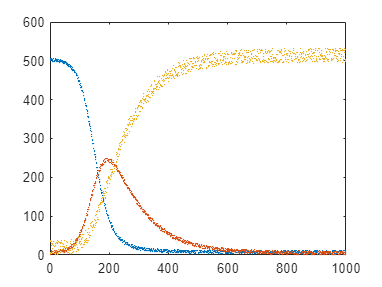


plot(tempo,Sdnew, '.' , 'markersize',0.8)
hold on;
plot(tempo,Idnew, '.' , 'markersize',0.8)
plot(tempo,Rdnew, '.' , 'markersize',0.8)
hold off;

## Utilizando o medo SIR feito no Simulink e visualizando dados

R0 = 0

R0 = 0

I0 = 499

I0 = 499

S0 = 1

S0 = 1

r = 0.1

r = 0.1000

beta = 0.0001

beta = 1.0000e-04

model = sim("ModeloSIR.slx")

model =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


SdValues = model.logsout{1}.Values.Data

SdValues =     1.0000
    0.9950
    0.9902
    0.9853
    0.9806
    0.9759
    0.9713
    0.9668
    0.9623
    0.9579


IdValues = model.logsout{2}.Values.Data

IdValues =   499.0000
  494.0349
  489.1191
  484.2522
  479.4338
  474.6632
  469.9401
  465.2640
  460.6344
  456.0508


RdValues = model.logsout{3}.Values.Data

RdValues =          0
    4.9701
    9.8907
   14.7624
   19.5856
   24.3608
   29.0885
   33.7692
   38.4033
   42.9913


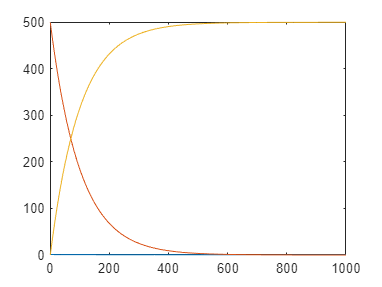

plot(SdValues)
hold on;
plot(IdValues)
plot(RdValues)
hold off;

## Calculando o erro do "chute" original

x0 = [r beta];
X = fminsearch(@(x) ErroQuadratico(x0,Sdnew,Idnew,Rdnew), x0)

X =     0.1000    0.0001



r = X(1)

r = 0.1000

beta = X(2)

beta = 1.0000e-04

model2 = sim("ModeloSIR.slx")

model2 =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [1000x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Visualizando e comparando os dados obtidos

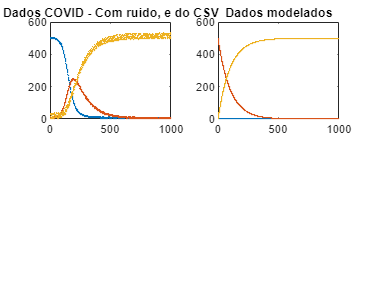

% Gráfico original
subplot(2,2,1)
plot(tempo,Sdnew, '.' , 'markersize',0.8)
hold on;
plot(tempo,Idnew, '.' , 'markersize',0.8)
plot(tempo,Rdnew, '.' , 'markersize',0.8)
hold off;
title('Dados COVID - Com ruido, e do CSV')

% Gráfico do modelo sir
subplot(2,2,2) 
plot(tempo, model2.logsout{1}.Values.Data, '.' , 'markersize',0.8)
hold on;
plot(tempo, model2.logsout{2}.Values.Data, '.' , 'markersize',0.8)
plot(tempo, model2.logsout{3}.Values.Data, '.' , 'markersize',0.8)
hold off;
title('Dados modelados')